## Задание 3. Сглаживание биржевых данных.

Скачаем данные стоимости акций различных компаний(Возьмём Роснефть) и применим к ним линейную фильтрацию первого порядка, чтобы выявить общую тенденцию движения графика

Последовательно будем брать следующие значения постоянной времени $T$:

1 день, 1 неделя, 1 месяц, 3 месяца, 1 год

Постройте сравнительные графики исходного и фильтрованного сигналов, красиво оформите результат

SBER_200101_240411.csv

ROSN_200101_240411.csv

table_stocks = readtable("SBER_200101_240411.csv");

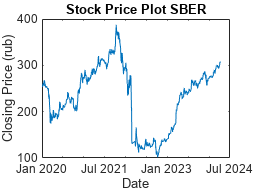


% Convert the date column to datetime format
date_num = table_stocks.x_DATE_;
year = floor(date_num / 10000);
month = floor(mod(date_num, 10000) / 100);
day = mod(date_num, 100);
date_datetime = datetime(2000+year, month, day);

% Format the datetime column as a string in the format 'yyMMdd'
table_stocks.DATE_formatted = date_datetime;


% Plot the closing price as a function of time
u = table_stocks.x_CLOSE_;
t = table_stocks.DATE_formatted;
figure(4324);
plot(t,u);
xlabel('Date');
ylabel('Closing Price (rub)');
title("Stock Price Plot " + table_stocks.x_TICKER_(1));
hold off;

% save_file("original_" + table_stocks.x_TICKER_(1))

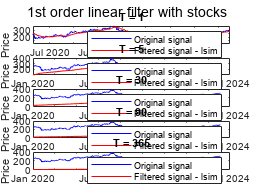

T = [1, 5, 30, 90, 365];
p = tf('p');
t_numbers = linspace(0,30,1064);

figure( randi([1 3000],1) )
sgtitle("1st order linear filter with stocks")
count = 1;
for i = 1:length(T)
  
        W1 = ss( 1/(T(count)*p + 1) );
        init_state = [u(1)];
        y = lsim(W1,u,t_numbers, init_state);

        subplot(5, 1, i)
        plot(t, u, 'b', t, y, 'r')
        title("T = " + T(count))
        ylabel('Price' + "       ");
        legend('Original signal', 'Filtered signal - lsim')
        count = count + 1;
    
end

% save_file(table_stocks.x_TICKER_(1))


Если сделать временную шкалу поменьше

**7 дней**

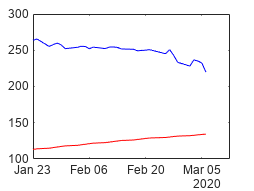

figure( randi([1 3000],1) )       
W1 = ss( 1/(T(2)*p + 1) );
init_state = [u(1)];
y = lsim(W1,u,t_numbers, init_state);

plot(t(14:14+30), u(14:14+30), 'b', t(14:14+30), y(14:14+30), 'r')

title("T = " + T(count))

Index exceeds the number of array elements. Index must not exceed 5.

ylabel('Price');
legend('Original signal', 'Filtered signal - lsim')
count = count + 1;

## Все функции, используемые в скрипте

**Save file in the folder**

function save_file(name)
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab4\plotting';

    

    Name = "test_stocks_" + name;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');

end